# Жесткие системы. Вариант 11

## Точное решение задачи Коши

Для поиска точного решения воспользуемся встроенными методами языка MATLAB

syms y1(t) y2(t);
cond1 = y1(0) == 0;
cond2 = y2(0) == 1;
ode1 = diff(y1) == -125*y1 + 123.55*y2;
ode2 = diff(y2) == 123.55*y1 -123*y2;
[y1sol,y2sol] = dsolve([ode1;ode2],[cond1;cond2]);
y1sol

$$y1sol = {\mathrm{e}}^{\frac{t\,\left(\sqrt{6106241}-2480\right)}{20}}\,\left(\frac{\sqrt{6106241}}{2471}-\frac{20}{2471}\right)\,\left(\frac{10\,\sqrt{6106241}}{6106241}+\frac{1}{2}\right)-\frac{\sqrt{6106241}\,{\mathrm{e}}^{-\frac{t\,\left(\sqrt{6106241}+2480\right)}{20}}\,\left(\frac{\sqrt{6106241}}{2471}+\frac{20}{2471}\right)\,\left(\sqrt{6106241}-20\right)}{12212482}$$

y2sol

$$y2sol = {\mathrm{e}}^{\frac{t\,\left(\sqrt{6106241}-2480\right)}{20}}\,\left(\frac{10\,\sqrt{6106241}}{6106241}+\frac{1}{2}\right)+\frac{\sqrt{6106241}\,{\mathrm{e}}^{-\frac{t\,\left(\sqrt{6106241}+2480\right)}{20}}\,\left(\sqrt{6106241}-20\right)}{12212482}$$

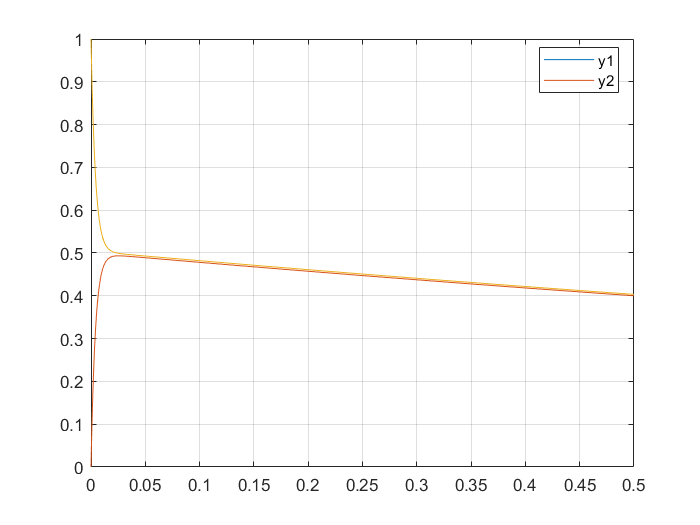

fplot(y1sol,[0 0.5])
hold on
fplot(y2sol,[0 0.5])
grid on
legend('y1','y2','Location','best')

Теперь построим вектор значений полученных ранее функций на отрезке $[0,0.5]$ с шагом h

h_acc=0.1;
x = 0:h_acc:0.5;
y1_mat = matlabFunction(y1sol);
y2_mat = matlabFunction(y2sol);
Y_acc_h1 = [y1_mat(x);y2_mat(x)]

Y_acc_h1 =    -0.0000    0.4782    0.4573    0.4374    0.4183    0.4001
    1.0000    0.4821    0.4610    0.4409    0.4217    0.4033


## Приближенное решение задачи Коши с шагом h = 0.05

Для начала введем матрицу системы

A = [-125,123.55;123.55,-123]

A =  -125.0000  123.5500
  123.5500 -123.0000


Подготовим входные данные для работы методов

h1 = 0.05;
x_h1 = 0:h1:0.5;
Y_h1 = zeros(2,size(x_h1,2));
Y_h1(2,1) = 1

Y_h1 =      0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0


### Явный метод Эйлера

Расчетная формула метода Эйлера имеет вид


$$Y_{i+1} = (E+Ah)Y_i$$


Реализация алгоритма находится в функции eulerMethod.m

[euler_y_h1,euler_w_h1] = eulerMethod(A,h1,Y_h1)

euler_y_h1 = 	1.0e+10 *

         0    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0012   -0.0140    0.1598   -1.8176
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0012    0.0139   -0.1585    1.8030


euler_w_h1 =    -5.2500    6.1775
    6.1775   -5.1500


### Неявный метод Эйлера

Расчетная формула невного метода Эйлера имеет вид


$$Y_{i+1} = (E-Ah)^{-1}Y_i$$


Реализация алгоритма находится в функции invEuler.m

[inv_euler_y_h1,inv_euler_w_h1] = invEuler(A,h1,Y_h1)

inv_euler_y_h1 =          0    0.4517    0.4756    0.4678    0.4578    0.4478    0.4380    0.4285    0.4191    0.4100    0.4010
    1.0000    0.5301    0.4851    0.4720    0.4615    0.4514    0.4416    0.4319    0.4225    0.4133    0.4043


inv_euler_w_h1 =     7.2500   -6.1775
   -6.1775    7.1500


### Интерполяционный метод Адамса третьего порядка

Расчетная формула интерполяционного метода Адамса имеет вид:


$$Y_{i+1} = \left(E - \frac{5hA}{12}\right)^{-1}\left(E+\frac{2hA}{3}\right)Y_i - \left(E - \frac{5hA}{12}\right)^{-1}\left(\frac{hA}{12}\right)Y_{i-1}$$


Реализация алгоритма находится в функции adamsMethod.m

[adams_y_h1,adams_w1_h1,adams_w2_h1] = adamsMethod(A,h1,inv_euler_y_h1)

adams_y_h1 =          0    0.4517    0.4386    0.5083    0.4030    0.5182    0.3449    0.5487    0.2605    0.6154    0.1308
    1.0000    0.5301    0.5216    0.4313    0.5151    0.3807    0.5329    0.3114    0.5784    0.2079    0.6706


adams_w1_h1 =    -0.1096    1.0769
    1.0769   -0.0921


adams_w2_h1 =    -0.0854    0.0828
    0.0828   -0.0840


## Проверка на устойчивость

### Метод Эйлера 

Для устойчивости метода Эйлера необходимо, чтобы все собственные числа матрицы перехода $W = (E + hA)$ были по модулю меньше 1. Найдем максимальное по модулю собственное число:

max_lambda = max(abs(eig(euler_w_h1)))

max_lambda = 11.3777

Оно намного больше 1. Соответственно, при h = 0.05 метод Эйлера не устойчив.

### Обратный метод Эйлера

Данный метод устойчив при любых h.

### Метод Адамса

Для устойчивости метода Адамса необходимо, чтобы все корни характеристических уравнений $(\mu^{(k)} )^2 - \lambda_k(W_1)\mu^{(k)} + \lambda_k(W_2) = 0,\ k=1,\dots,n$ были по модулю меньше 1. 

 Найдем собственные числа матриц $W_1 $ и $W_2
$:

lambda_W1_h1 = eig(adams_w1_h1)

lambda_W1_h1 =    -1.1777
    0.9761


lambda_W2_h1 = eig(adams_w2_h1)

lambda_W2_h1 =    -0.1675
   -0.0018


Найдем корни характеристических уравнений:

first_char_eq = [1 -lambda_W1_h1(1) lambda_W2_h1(1)];
second_char_eq = [1 -lambda_W1_h1(2) lambda_W2_h1(2)];
first_roots_h1 = roots(first_char_eq);
second_roots_h1 = roots(second_char_eq);

Нас интересуют максимальные по модулю корни, поэтому рассмотрим только их.

max_of_first_roots_h1 = max(abs(first_roots_h1))

max_of_first_roots_h1 = 1.3060

max_of_2nd_roots_h1 = max(abs(second_roots_h1))

max_of_2nd_roots_h1 = 0.9779

Первое уравнение имеет корень, по модулю больший, чем 1. Значит, метод Адамса тоже не является устойчивым для h = 0.05

## Приближенное решение задачи Коши с шагом h = 0.001

Повторим все выполненные ранее операции с новым шагом

h2 = 0.001;
x_h2 = 0:h2:0.5

x_h2 =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


Y_h2 = zeros(2,size(x_h2,2));
Y_h2(2,1) = 1

Y_h2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


### Метод Эйлера

[euler_y_h2,euler_w_h2] = eulerMethod(A,h2,Y_h2) 

euler_y_h2 =          0    0.1235    0.2165    0.2863    0.3388    0.3783    0.4079    0.4301    0.4468    0.4593    0.4687    0.4756    0.4808    0.4847    0.4875    0.4896    0.4911    0.4922    0.4930    0.4935    0.4939    0.4940    0.4941    0.4942    0.4941    0.4940    0.4939    0.4938    0.4936    0.4934    0.4932    0.4930    0.4928    0.4926    0.4924    0.4922    0.4920    0.4918    0.4916    0.4914    0.4911    0.4909    0.4907    0.4905    0.4903    0.4900    0.4898    0.4896    0.4894    0.4892
    1.0000    0.8770    0.7844    0.7147    0.6621    0.6225    0.5927    0.5702    0.5532    0.5404    0.5307    0.5233    0.5177    0.5134    0.5102    0.5076    0.5057    0.5042    0.5030    0.5020    0.5012    0.5006    0.5001    0.4996    0.4992    0.4989    0.4985    0.4982    0.4980    0.4977    0.4974    0.4972    0.4970    0.4967    0.4965    0.4963    0.4960    0.4958    0.4956    0.4954    0.4951    0.4949    0.4947    0.4945    0.4943    0.4940    0.4938    0.4936    0.

euler_w_h2 =     0.8750    0.1235
    0.1235    0.8770


### Обратный метод Эйлера

[inv_euler_y_h2] = invEuler(A,h2,Y_h2)

inv_euler_y_h2 =          0    0.0990    0.1783    0.2418    0.2927    0.3334    0.3660    0.3921    0.4130    0.4297    0.4430    0.4537    0.4621    0.4689    0.4743    0.4785    0.4819    0.4846    0.4867    0.4883    0.4896    0.4905    0.4913    0.4918    0.4922    0.4925    0.4926    0.4927    0.4928    0.4927    0.4927    0.4926    0.4925    0.4923    0.4922    0.4920    0.4918    0.4917    0.4915    0.4913    0.4911    0.4909    0.4907    0.4905    0.4902    0.4900    0.4898    0.4896    0.4894    0.4892
    1.0000    0.9014    0.8223    0.7588    0.7079    0.6670    0.6342    0.6079    0.5868    0.5698    0.5561    0.5451    0.5362    0.5291    0.5233    0.5187    0.5149    0.5118    0.5093    0.5072    0.5055    0.5041    0.5029    0.5020    0.5011    0.5004    0.4998    0.4993    0.4988    0.4984    0.4980    0.4976    0.4973    0.4970    0.4967    0.4965    0.4962    0.4959    0.4957    0.4954    0.4952    0.4950    0.4947    0.4945    0.4943    0.4941    0.4938    0.4936  

### Метод Адамса

[adams_y_h2, adams_w1_h2,adams_w2_h2] = adamsMethod(A,h2,inv_euler_y_h2)

adams_y_h2 =          0    0.0990    0.1868    0.2551    0.3084    0.3500    0.3824    0.4077    0.4273    0.4426    0.4545    0.4638    0.4710    0.4765    0.4808    0.4841    0.4866    0.4886    0.4900    0.4911    0.4919    0.4925    0.4929    0.4931    0.4933    0.4934    0.4934    0.4934    0.4933    0.4932    0.4930    0.4929    0.4927    0.4925    0.4923    0.4922    0.4920    0.4917    0.4915    0.4913    0.4911    0.4909    0.4907    0.4905    0.4903    0.4900    0.4898    0.4896    0.4894    0.4892
    1.0000    0.9014    0.8138    0.7456    0.6923    0.6506    0.6180    0.5925    0.5726    0.5569    0.5447    0.5351    0.5275    0.5215    0.5168    0.5131    0.5102    0.5078    0.5059    0.5044    0.5032    0.5022    0.5013    0.5006    0.5000    0.4995    0.4991    0.4987    0.4983    0.4980    0.4977    0.4974    0.4971    0.4968    0.4966    0.4963    0.4961    0.4959    0.4956    0.4954    0.4952    0.4949    0.4947    0.4945    0.4943    0.4940    0.4938    0.4936    0.

adams_w1_h2 =     0.8772    0.1213
    0.1213    0.8792


adams_w2_h2 =    -0.0094    0.0093
    0.0093   -0.0093


## Повторная проверка на устойчивость

### Метод Эйлера 

 Найдем максимальное по модулю собственное число:

max_lambda_h2 = max(abs(eig(euler_w_h2)))

max_lambda_h2 = 0.9996

Оно меньше 1. Соответственно, при h = 0.001 метод Эйлера устойчив.

### Метод Адамса

Найдем собственные числа матриц $W_1 $ и $W_2
$:

lambda_W1_h2 = eig(adams_w1_h2)

lambda_W1_h2 =     0.7569
    0.9995


lambda_W2_h2 = eig(adams_w2_h2)

lambda_W2_h2 =    -0.0187
   -0.0000


Найдем корни характеристических уравнений:

first_char_eq_h2 = [1 -lambda_W1_h2(1) lambda_W2_h2(1)];
second_char_eq_h2 = [1 -lambda_W1_h2(2) lambda_W2_h2(2)];
first_roots_h2 = roots(first_char_eq_h2);
second_roots_h2 = roots(second_char_eq_h2);

Нас интересуют максимальные по модулю корни, поэтому рассмотрим только их.

max_of_first_roots_h2 = max(abs(first_roots_h2))

max_of_first_roots_h2 = 0.7808

max_of_2nd_roots_h2 = max(abs(second_roots_h2))

max_of_2nd_roots_h2 = 0.9996

Все корни по модулю меньше 1. Значит, метод Адамса тоже является устойчивым для h = 0.001

## Результат

### Метод Эйлера

#### С шагом h1 = 0.05

В таблице ниже представлен модуль разности между точным решением и решением, полученным методом Эйлера, в точках [0, 0.1, 0.2, 0.3, 0.4, 0.5].

euler_h1_table =array2table(abs(Y_acc_h1 - euler_y_h1(:,1:2:11)));
euler_h1_table.Properties.RowNames = {'y*1 - y1', 'y*2-y2'};
euler_h1_table.Properties.Description = 'Разница между точным и полученным значениями';
euler_h1_table.Properties.VariableNames = {'0','0.1','0.2','0.3','0.4','0.5'}

euler_h1_table = 2×6 table
                    0          0.1       0.2         0.3           0.4           0.5    
                __________    ______    ______    __________    __________    __________

    y*1 - y1    1.1102e-16    64.724    8378.7    1.0846e+06    1.4041e+08    1.8176e+10
    y*2-y2               0    64.202    8311.1    1.0759e+06    1.3928e+08     1.803e+10


По таблице легко можно заметить неустойчивость метода Эйлера при данном значении h.

#### С шагом h2 = 0.001

Ниже приведена аналогичная предыдущему пункту таблица модулей разности для решения, полученного с шагом h.

euler_h2_table =array2table(abs(Y_acc_h1 - euler_y_h2(:,1:100:501)));
euler_h2_table.Properties.RowNames = {'y*1 - y1', 'y*2-y2'};
euler_h2_table.Properties.Description = 'Разница между точным и полученным значениями';
euler_h2_table.Properties.VariableNames = {'0','0.1','0.2','0.3','0.4','0.5'}

euler_h2_table = 2×6 table
                    0            0.1           0.2           0.3           0.4           0.5    
                __________    __________    __________    __________    __________    __________

    y*1 - y1    1.1102e-16    4.7562e-06    9.0975e-06    1.3051e-05    1.6642e-05    1.9896e-05
    y*2-y2               0    4.7949e-06    9.1715e-06    1.3157e-05    1.6778e-05    2.0057e-05


При рассмотрении таблицы устойчивость метода Эйлера с шагом h2 становится очевидной.

### Обратный метод Эйлера

Если сравнить 2 таблицы, с легкостью можно заметить тот факт, что обратный метод Эйлера устойчив при обоих значениях h

inv_euler_h1_table =array2table(abs(Y_acc_h1 - inv_euler_y_h1(:,1:2:11)));
inv_euler_h1_table.Properties.RowNames = {'y*1 - y1', 'y*2-y2'};
inv_euler_h1_table.Properties.Description = 'Разница между точным и полученным значениями';
inv_euler_h1_table.Properties.VariableNames = {'0','0.1','0.2','0.3','0.4','0.5'}

inv_euler_h1_table = 2×6 table
                    0            0.1          0.2           0.3           0.4           0.5    
                __________    _________    __________    __________    __________    __________

    y*1 - y1    1.1102e-16    0.0025595    0.00043271    0.00064322    0.00082053    0.00098117
    y*2-y2               0    0.0030075    0.00046745    0.00064862     0.0008272    0.00098914


inv_euler_h2_table =array2table(abs(Y_acc_h1 - inv_euler_y_h2(:,1:100:501)));
inv_euler_h2_table.Properties.RowNames = {'y*1 - y1', 'y*2-y2'};
inv_euler_h2_table.Properties.Description = 'Разница между точным и полученным значениями';
inv_euler_h2_table.Properties.VariableNames = {'0','0.1','0.2','0.3','0.4','0.5'}

inv_euler_h2_table = 2×6 table
                    0            0.1           0.2           0.3           0.4           0.5    
                __________    __________    __________    __________    __________    __________

    y*1 - y1    1.1102e-16    4.7533e-06    9.0923e-06    1.3044e-05    1.6633e-05    1.9885e-05
    y*2-y2               0    4.7922e-06    9.1662e-06     1.315e-05    1.6768e-05    2.0046e-05


### Метод Адамса

#### С шагом h1 = 0.05

В данном случае неустойчивость метода не столь очевидна, как в случае с методом Эйлера, однако заметно, что метод имеет достаточно большую погрешность

adams_h1_table =array2table(abs(Y_acc_h1 - adams_y_h1(:,1:2:11)));
adams_h1_table.Properties.RowNames = {'y*1 - y1', 'y*2-y2'};
adams_h1_table.Properties.Description = 'Разница между точным и полученным значениями';
adams_h1_table.Properties.VariableNames = {'0','0.1','0.2','0.3','0.4','0.5'}

adams_h1_table = 2×6 table
                    0           0.1         0.2         0.3         0.4        0.5  
                __________    ________    ________    ________    _______    _______

    y*1 - y1    1.1102e-16    0.039622    0.054293    0.092469     0.1578    0.26922
    y*2-y2               0    0.039537    0.054079    0.091937    0.15673    0.26725


#### С шагом h2 = 0.001

Согласно таблице, метод  Адамса с шагом h2 устойчив.

adams_h2_table =array2table(abs(Y_acc_h1 - adams_y_h2(:,1:100:501)));
adams_h2_table.Properties.RowNames = {'y*1 - y1', 'y*2-y2'};
adams_h2_table.Properties.Description = 'Разница между точным и полученным значениями';
adams_h2_table.Properties.VariableNames = {'0','0.1','0.2','0.3','0.4','0.5'}

adams_h2_table = 2×6 table
                    0            0.1           0.2           0.3           0.4           0.5    
                __________    __________    __________    __________    __________    __________

    y*1 - y1    1.1102e-16    4.7532e-08     4.546e-08    4.3477e-08    4.1581e-08    3.9767e-08
    y*2-y2               0    4.7919e-08    4.5829e-08     4.383e-08    4.1919e-08     4.009e-08
